clc, clearvars

# **MRI local wire simulation**

The purpose of wire_function() is to simulate the path of a local wire through the body in the electric field.  

## **Required Inputs**

eField (as a file name):

"simulatedBodyCoilEfield (1).mat"

ans = "simulatedBodyCoilEfield (1).mat"

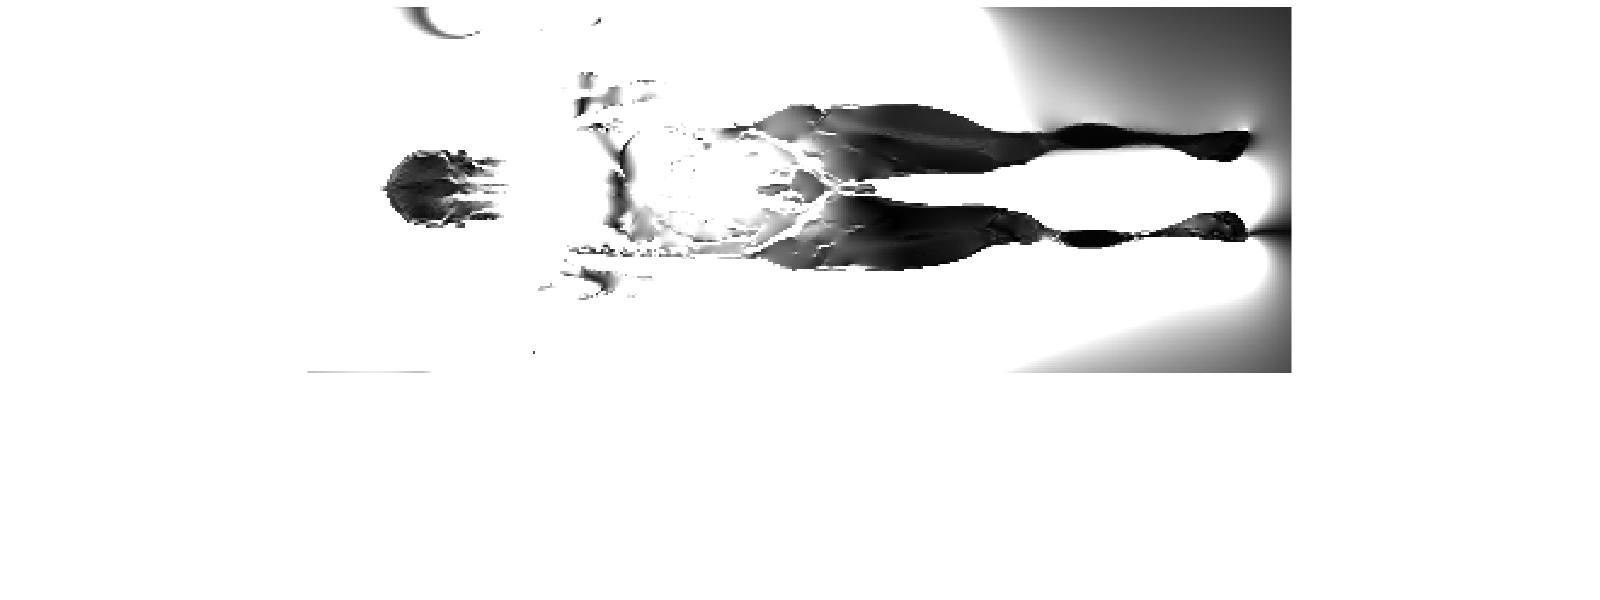

z =    94.5820
  135.0137
  192.7732
  351.1995


x =    76.6189
   82.3948
   77.4440
   17.2090


s = load(ans);
title('Saggital')
imshow(squeeze(abs(s.E(:,75,:,1))))
set(gcf,'Position',[300 300 800 300])
[z, x] = getpts

Pick your points for the y direction on the green lines. 

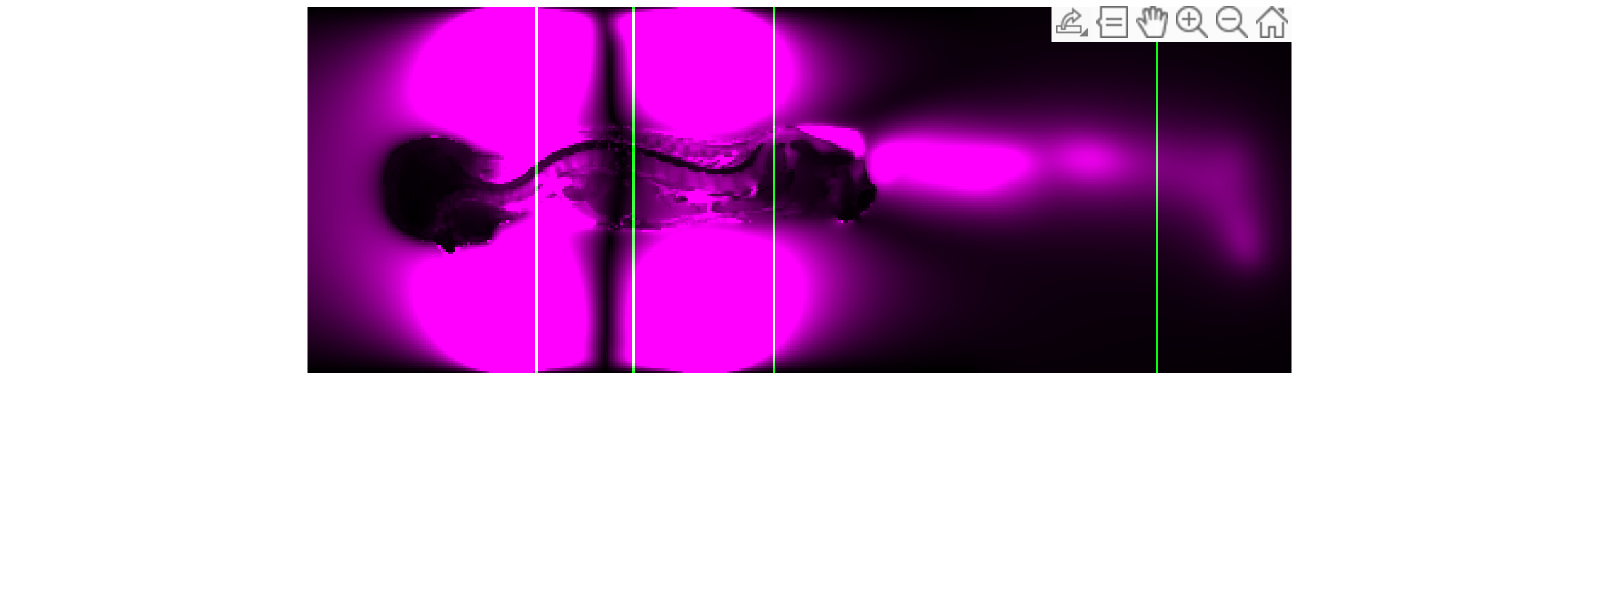


vol = zeros(length(s.axis1)-1, length(s.axis2)-1);
vol(:,round(z)) = 1;

s.E(abs(s.E) > 5) = 5;
imshow(imfuse(vol, squeeze(abs(s.E(75,:,:,1)) ), 'Scaling', 'independent')) 
set(gcf,'Position',[300 300 800 300])
[zc, y] = getpts;

p = [x, y, z];
points = convert_points(p, s, 'version', "v1")

output =      1     1     1
     1     1     1
     1     1     1
     1     1     1


points =     0.0033   -0.0267   -0.1492
    0.0283   -0.0217    0.0508
    0.0033   -0.0367    0.3408
   -0.2967   -0.2667    1.1308


num_points = size(points, 1);     

Pick the minimum and maximum values for each of your points. 

1) Select a value above and below for the x direction.

2) Select a value to the right and left when choosing z ranges. 

3) Select a value above and below for the y direction. 

Coordinates that you do not specify as changing later on will not be used. **Pick maximum first and minimum second for each point. **

y ranges:

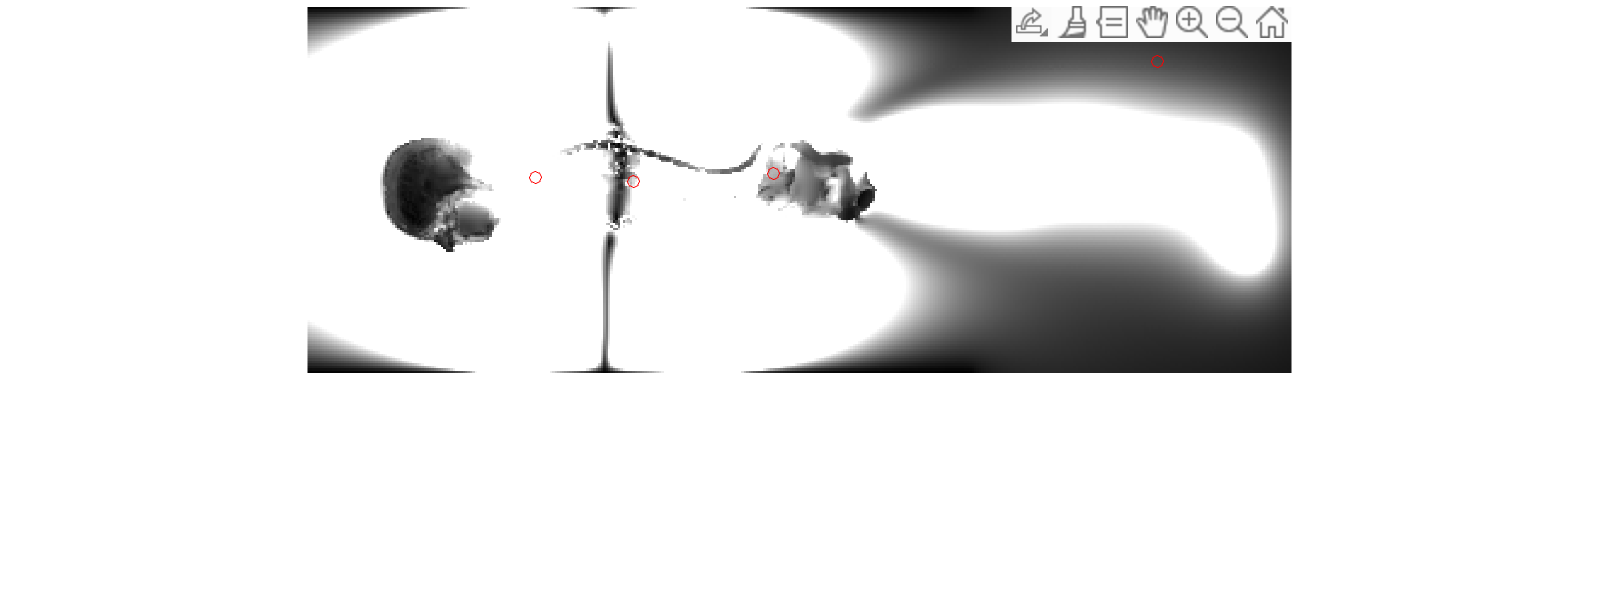

zn =    94.5820
   95.4071
  132.5383
  133.3634
  196.0738
  196.0738
  352.0246
  351.1995


y_ranges =    63.4167
   82.3948
   60.1161
   84.8702
   59.2910
   77.4440
   18.8593
   31.2363


%voll = zeros(length(s.axis1)-1, length(s.axis2)-1);
%voll(round(points()),round(points(:, 1:2))) = 1; %how to only do points?
imshow(squeeze(abs(s.E(75,:,:,1))) )
set(gcf,'Position',[300 300 800 300])
hold on,
plot(z, y, 'ro');
hold off
[zn, y_ranges] = getpts

y_ranges = reshape(y_ranges, 2, num_points)' %check if order is correct

y_ranges =    63.4167   82.3948
   60.1161   84.8702
   59.2910   77.4440
   18.8593   31.2363


y_ranges = convert_points(y_ranges, s, 'version', "v2", 'yd', "T")

y_ranges =    -0.0667    0.0283
   -0.0817    0.0433
   -0.0867    0.0033
   -0.2867   -0.2267


z ranges:

z_ranges =    82.2049
  107.7842
  124.2869
  144.0902
  182.8716
  205.9754
  338.8224
  375.9536


yn =    71.6680
   71.6680
   74.1434
   74.1434
   70.0178
   69.1926
   23.8101
   24.6352


%same plot
imshow(squeeze(abs(s.E(75,:,:,1))) )
set(gcf,'Position',[300 300 800 300])
hold on,
plot(z, y, 'ro');
hold off
[z_ranges, yn] = getpts

z_ranges = reshape(z_ranges, 2, num_points)'%convert points

z_ranges =    82.2049  107.7842
  124.2869  144.0902
  182.8716  205.9754
  338.8224  375.9536


z_ranges = convert_points(z_ranges, s, 'version', "v2", 'zd', "T")

z_ranges =    -0.2142   -0.0842
   -0.0042    0.0958
    0.2908    0.4058
    1.0708    1.2558


x ranges:

imshow(squeeze(abs(s.E(:,75,:,1))) )
set(gcf,'Position',[300 300 800 300])
hold on,
plot(z, x, 'ro');
hold off
[zn, x_ranges] = getpts

zn =    95.4071
   95.4071
  135.8388
  135.8388
  191.1230
  192.7732
  351.1995
  351.1995


x_ranges =    62.5915
   92.2964
   60.9413
   93.1216
   60.1161
   89.8210
   17.2090
   30.4112


x_ranges = reshape(x_ranges, 2, num_points)'

x_ranges =    62.5915   92.2964
   60.9413   93.1216
   60.1161   89.8210
   17.2090   30.4112


x_ranges = convert_points(x_ranges, s, 'version', "v2", 'xd', "T")

x_ranges =    -0.0667    0.0783
   -0.0767    0.0833
   -0.0817    0.0683
   -0.2967   -0.2317


ranges = [x_ranges y_ranges z_ranges];

which points will be changing (give a list of their indices): 

[1 2 3]

ans =      1     2     3


check of all of the points that are changing:

changing = ans;

## **Optional Inputs**

Drag to choose how long you want your wire to be. Your points will be adjusted to this length. Units are in meters. 

2

ans = 2

nom_length = ans;

Do you want a plot of the wire to be displayed?

"No"

ans = "No"

if ans == "Yes"
    show_plot = true;
else
    show_plot = false;
end

Do you want a histogram of the lengths of the trajectories for the wire (modified and unmodified) to be displayed?

"Yes"

ans = "Yes"

if ans == 'Yes'
    show_graph = true;
else
    show_graph = false;
end

What is the indice of the point on the wire that intersects with the body?

3

ans = 3

intersecting = ans;

Drag to pick the number of steps between ranges. For example, if there is a range [-1 2] and num_steps is 3, the function will use 3 values in between -1  and 2. Default value: 5. num_steps^3 is the number of trajectories that will be calculated. 

5

ans = 5

num_steps = ans;
set(gcf,'Position',[300 300 700 700]) %weird transition

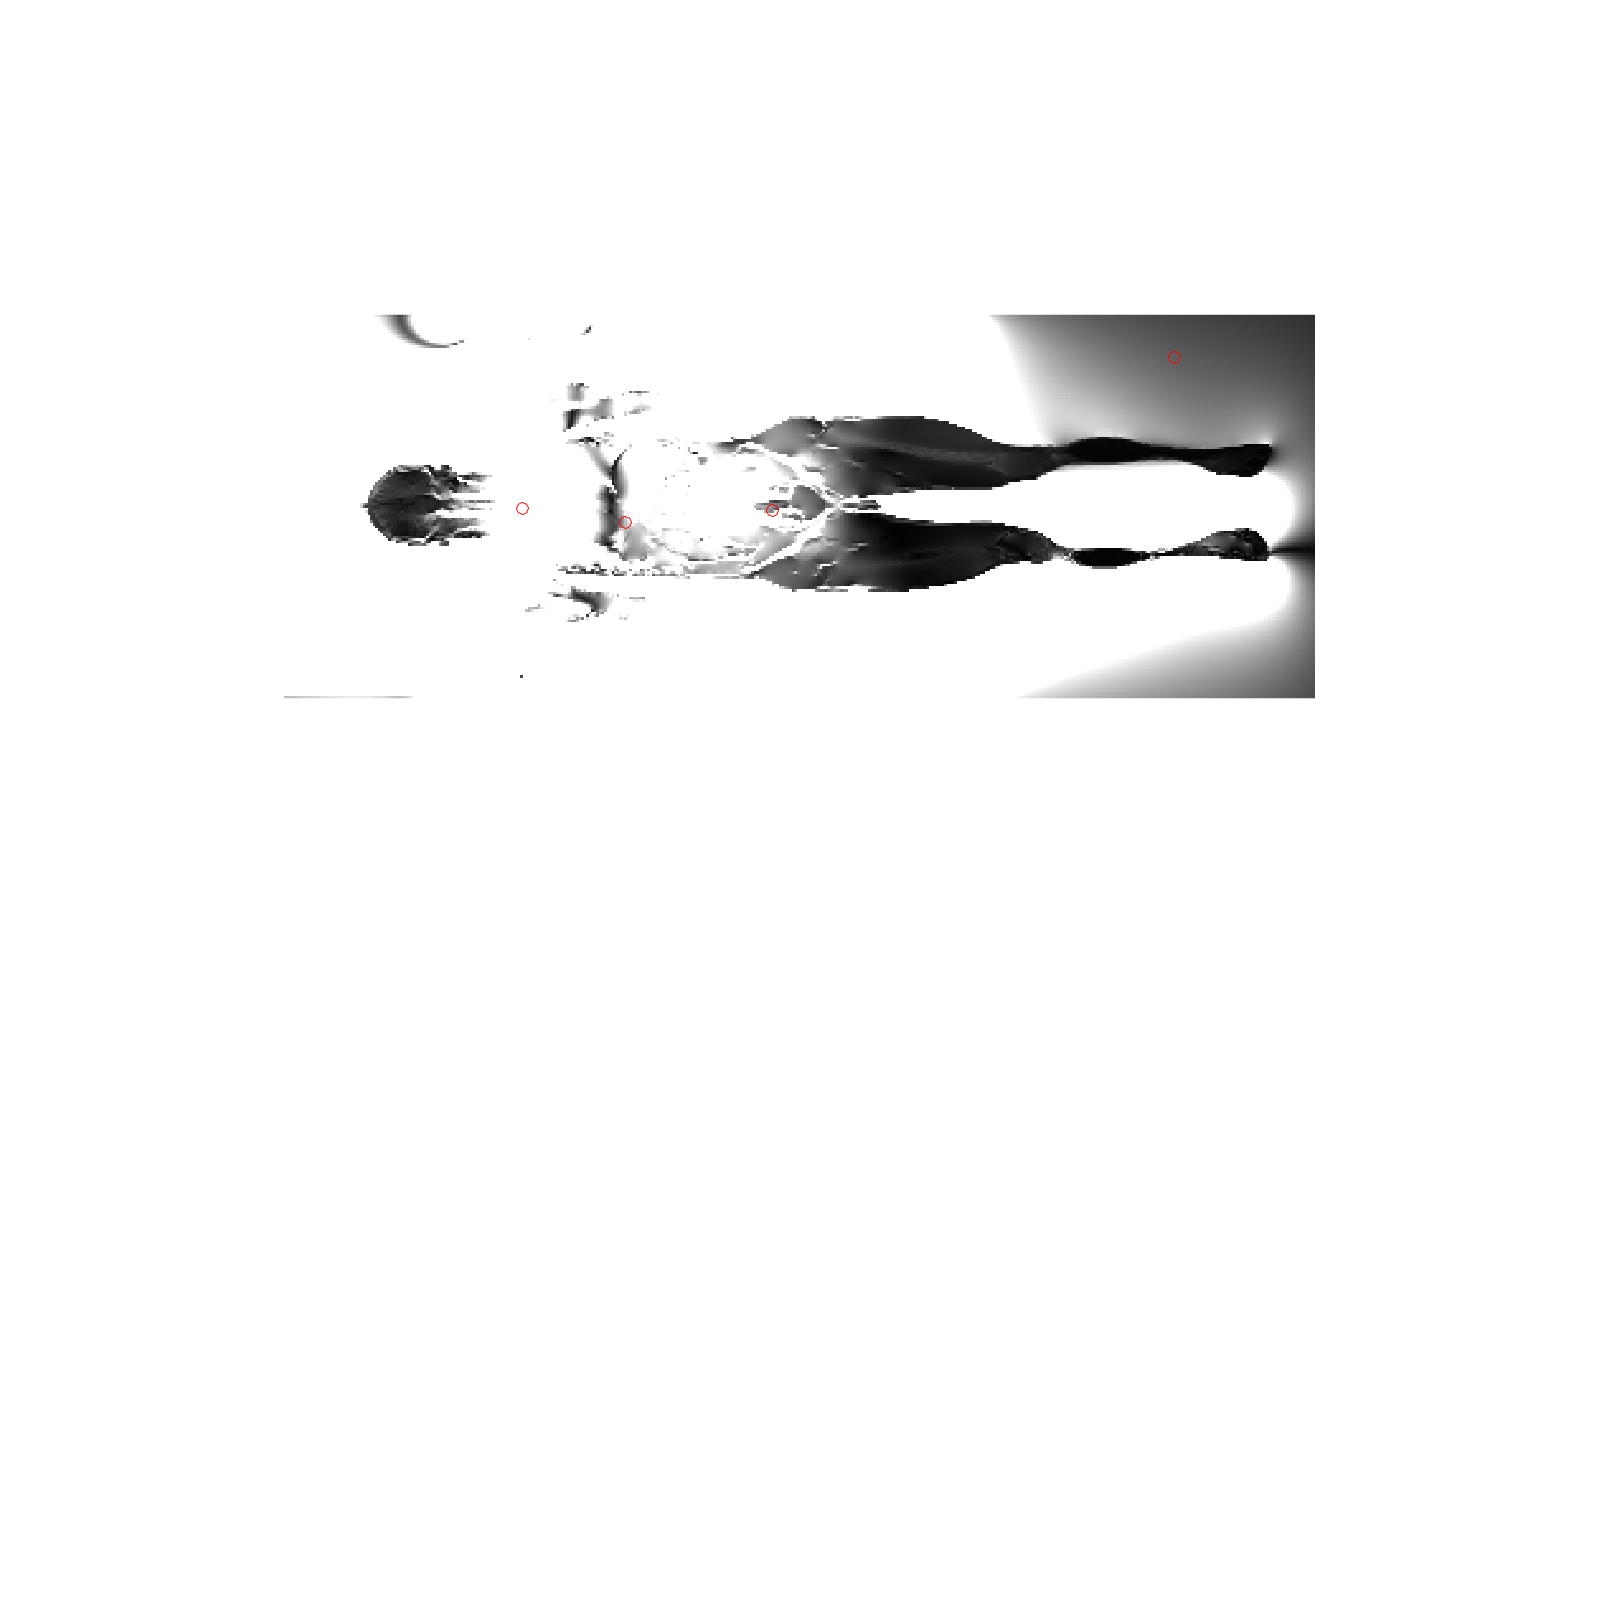

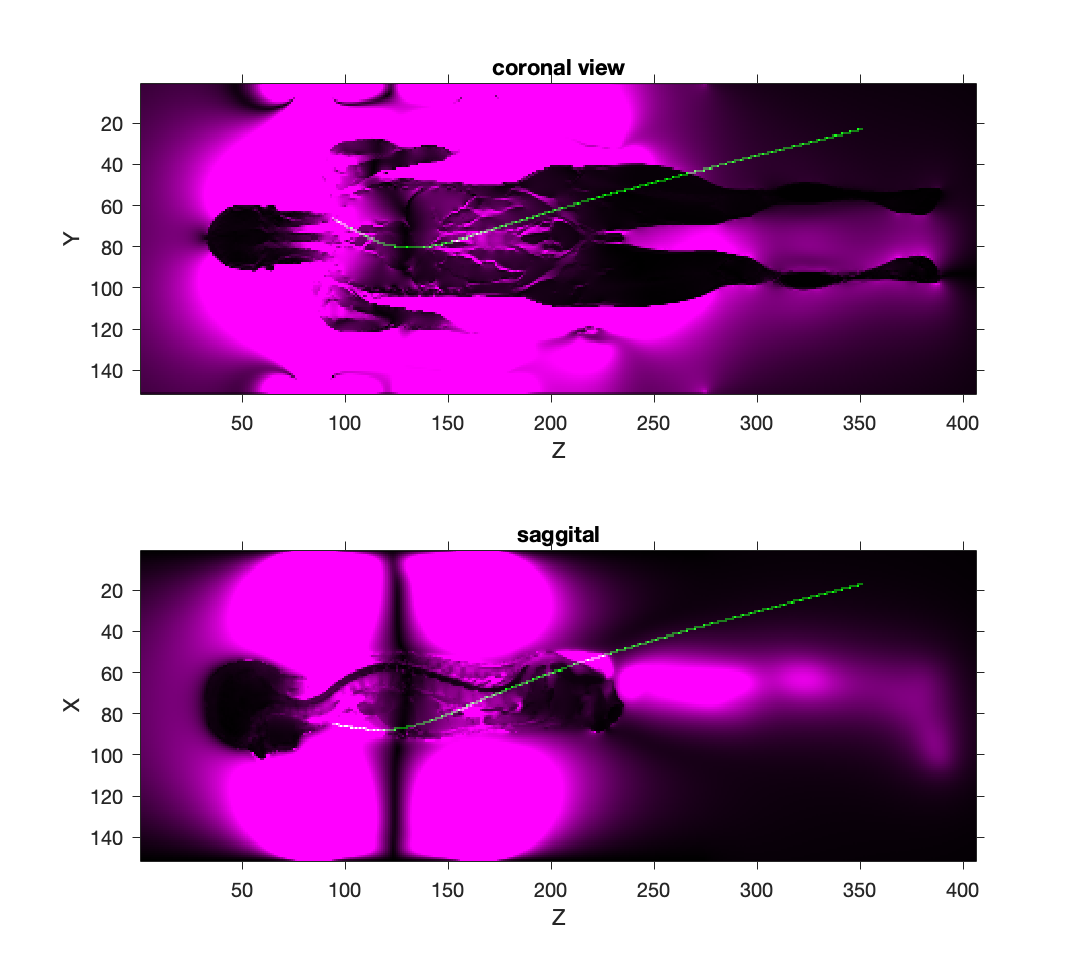

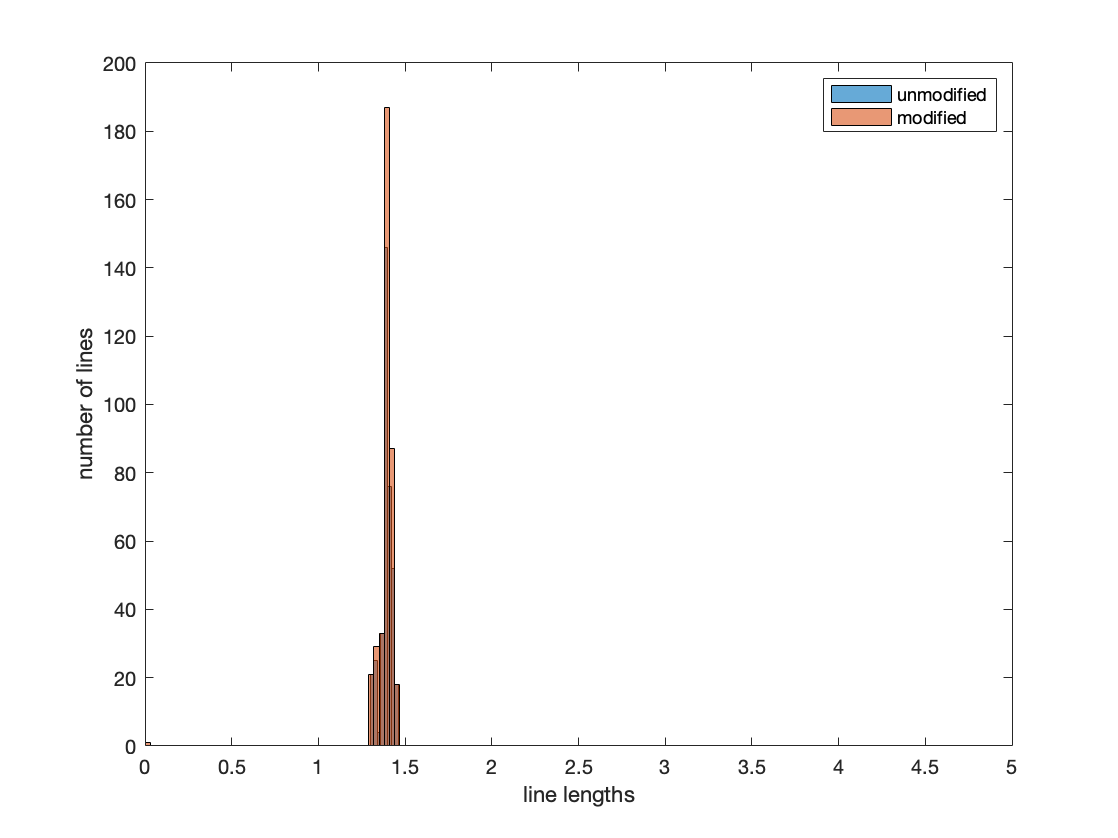

wire_function_v5(...
    points',...
    ranges,...
    changing,...
    s,...
    'nom_length', nom_length,...
    'show_plot', show_plot,...
    'show_graph', show_graph,...
    'intersecting_index', intersecting,...
    'num_steps', num_steps,...
    'give_warnings', false);